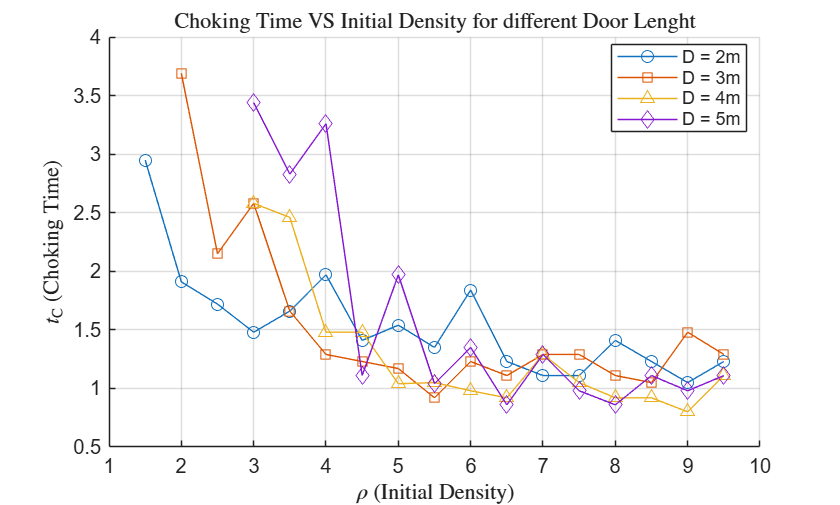

% This will plot the chocking time and inflow flux
initial_density = [0.5, 1.0, 1.5, 2.0, 2.5, 3.0, 3.5, 4.0, 4.5, 5.0, 5.5, 6.0, 6.5, 7.0, 7.5, 8.0, 8.5, 9.0, 9.5];
% These are the time of chocking for each of them
door_1_choking = [NaN, NaN, 2.95, 1.91, 1.72, 1.48, 1.66, 1.97, 1.41, 1.54, 1.35, 1.84, 1.23, 1.11, 1.11, 1.41, 1.23, 1.05, 1.23];
door_2_choking = [NaN, NaN, NaN, 3.69, 2.15, 2.58, 1.66, 1.29, 1.23, 1.17, 0.92, 1.23, 1.11, 1.29, 1.29, 1.11, 1.05, 1.48, 1.29];
door_3_choking = [NaN, NaN, NaN, NaN, NaN, 2.58, 2.46, 1.48, 1.48, 1.04, 1.05, 0.98, 0.92, 1.29, 1.05, 0.92, 0.92, 0.80, 1.11];
door_4_choking = [NaN, NaN, NaN, NaN, NaN, 3.44, 2.83, 3.26, 1.11, 1.97, 1.04, 1.35, 0.86, 1.29, 0.98, 0.86, 1.11, 0.98, 1.11];

figure;
hold on;

plot(initial_density, door_1_choking, 'o-', 'DisplayName', 'D = 2m');
plot(initial_density, door_2_choking, 's-', 'DisplayName', 'D = 3m');
plot(initial_density, door_3_choking, '^-', 'DisplayName', 'D = 4m');
plot(initial_density, door_4_choking, 'd-', 'DisplayName', 'D = 5m');
title("Choking Time VS Initial Density for different Door Lenght", 'Interpreter', 'latex');
xlabel('$\rho$ (Initial Density)', 'Interpreter', 'latex');
ylabel('$t_{\mathrm{C}}$ (Choking Time)', 'Interpreter', 'latex');
legend('Location', 'best');
grid on;

hold off;
% Save the figure
saveas(gcf, "Choking_Time_vs_Initial_Density.png");

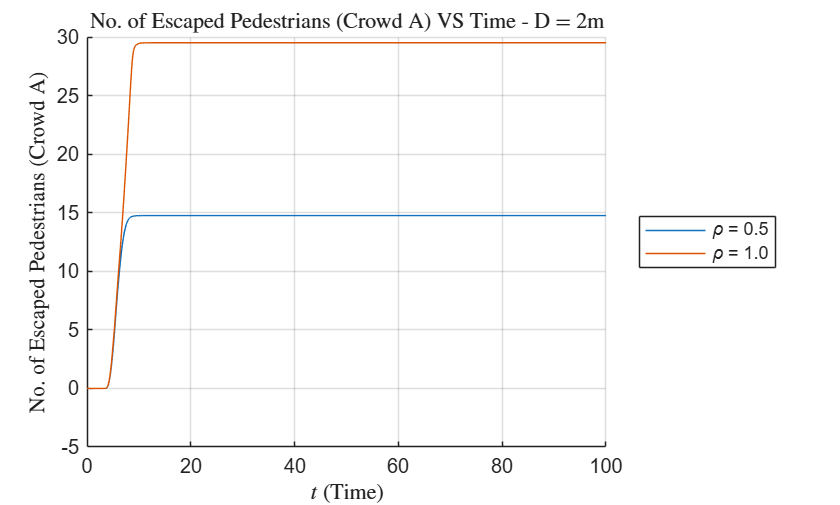

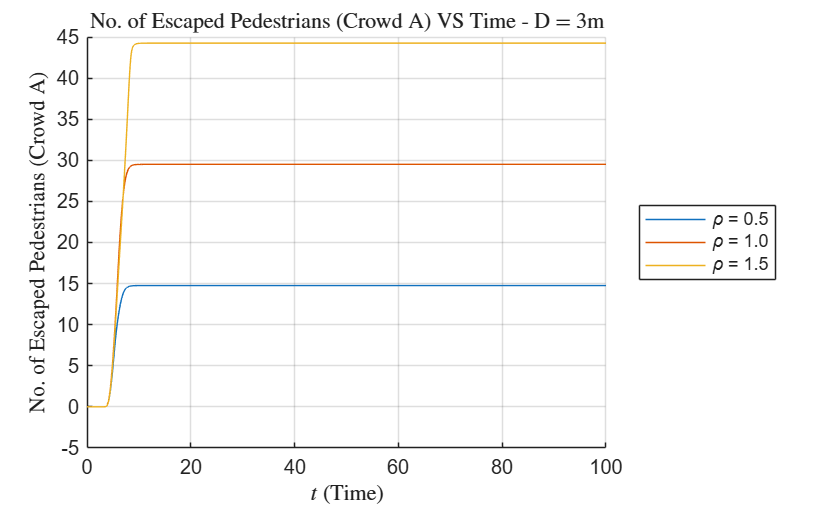

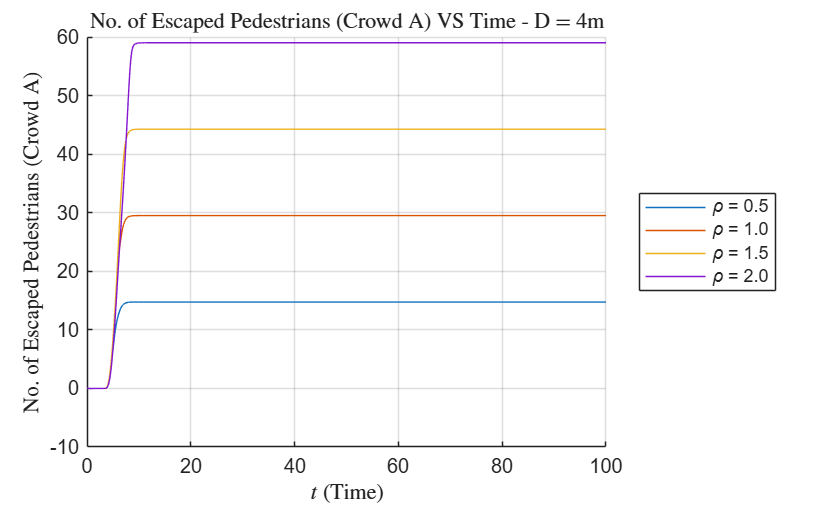

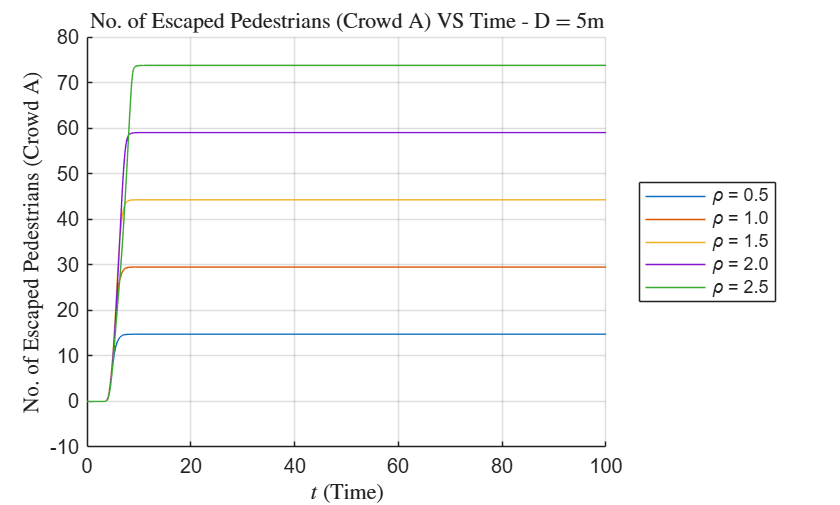


% Plot escaped pedestrians for each door

for door = 1:4

    door_folder = sprintf("Door_%d", door);

    figure;
    hold on;

    switch door
        case 1
            final_density = 1;
            
        case 2
            final_density = 1.5;
            
        case 3
            final_density = 2.0;
           
        case 4
            final_density = 2.5;
            
    end

    for escape_ped = 0.5:0.5:final_density

        fileName = fullfile( ...
            door_folder, ...
            sprintf("Escaped_pedestrians_D_%.2f_rho_%.2f_Crowd_A.csv",door, escape_ped));

        data = readmatrix(fileName);

        time = data(:,2);
        esc_ped = data(:,1);

        % Plot escaped pedestrians against time
        plot(time, esc_ped, '-','DisplayName', sprintf('\\rho = %.1f', escape_ped));

    end

    xlabel('$t$ (Time)', 'Interpreter', 'latex')
    ylabel('No. of Escaped Pedestrians (Crowd A)', 'Interpreter', 'latex');
    title(sprintf("No. of Escaped Pedestrians (Crowd A) VS Time - D = %dm", door+1), 'Interpreter', 'latex');

    grid on;

    % Legend outside the plot
    legend('Location', 'eastoutside');
    lgd.Interpreter = 'latex';

    hold off;

    % Save the figure
    plot_name = sprintf('Ped_Esc_VS_Door_%d.png', door);
    saveas(gcf, plot_name);

end